# `Beamforming ULA spectral estimation`

`First, simulate signals`

numElements = 4;
c = physconst('LightSpeed');
fc = 2.44e9;              % Operating frequency
lambda = c/fc;
d = 0.5*lambda; % Element spacing
ula = phased.ULA('NumElements',numElements,'ElementSpacing',d);

ang1 = [40];          % First signal
ang2 = [-20];         % Second signal
angs = [ang1 ang2];

pos = getElementPosition(ula)/lambda;

Nsamp = 128;

nPower = 0.01; % thermal noise [W] at each antenna
nSignal = 1; % signal power [W] at each antenna

rs = rng(2007); % random number generator
signal = sensorsig(pos,Nsamp,angs,nPower, nSignal); % signal of interest (SOI)

Calculate covariance matrix

R = (signal' * signal)/Nsamp;

Calculate spectrum of MVDR beamformer

There are two ways: one which calculates the weighted steering vector, $\omega$, and uses that to estimate power.

The other calculates power directly which will be more efficient if you are not interested in the weighted steering vector.

theta_scan = -90:1:90;   % Range of angles to scan
sz_sig = [length(theta_scan) height(signal)]; % theta_scan x snapshot
sig_mvdr = zeros(sz_sig);
sig_cbf = zeros(sz_sig);
sig_cbf_manual = zeros(sz_sig);
sz_scan = size(theta_scan);
P_mvdr2 = zeros(sz_scan);  % Initialize power vector
sz_s_vecs = [numElements length(theta_scan)];
s_vecs = zeros(sz_s_vecs);
s_vecs_manual = zeros(sz_s_vecs);

n = transpose(0:numElements-1); % [0, 1, 2, ..., numElements-1]

for i = 1:length(theta_scan)
    ang = [theta_scan(i)];  % Current scan angle
    steering_vector = phased.SteeringVector('SensorArray',ula,'PropagationSpeed',c);
    s = steering_vector(fc, -ang);
    s_manual = exp(-1j * 2 * pi * (d/lambda) * n * sin(deg2rad(ang)));
    s_vecs(1:numElements, i) = s*s(1)'; % scale so s(1) = 1 is the reference
    s_vecs_manual(1:numElements, i) = s_manual;
    w = inv(R) * (s / (s' * inv(R) * s));
    sig_mvdr(i,1:Nsamp) = signal * w;
    sig_cbf(i,1:Nsamp) = signal * s;
    sig_cbf_manual(i,1:Nsamp) = signal * s_manual;
    P_mvdr2(i) = real(1 / (s' * inv(R) * s));  % MVDR spectral power
end
P_mvdr = mean(abs(sig_mvdr).^2, 2);
P_cbf = mean(abs(sig_cbf).^2, 2);
P_cbf_manual = mean(abs(sig_cbf_manual).^2, 2);

Plot CBF steering vectors (to check they are the same).

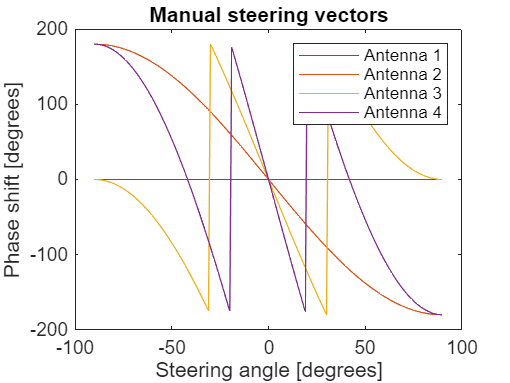

figure;
plot(theta_scan, rad2deg(angle(s_vecs_manual)));
title("Manual steering vectors");
xlabel("Steering angle [degrees]");
ylabel("Phase shift [degrees]");
legend('Antenna 1', 'Antenna 2', 'Antenna 3', 'Antenna 4');

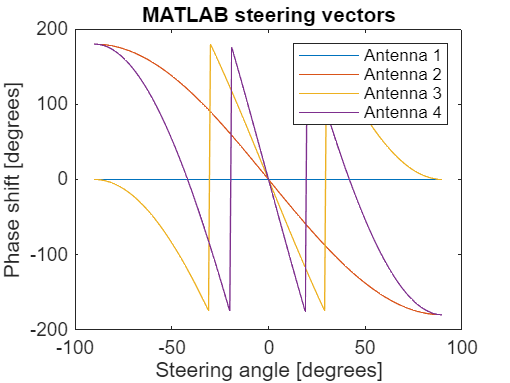

plot(theta_scan, rad2deg(angle(s_vecs)));
title("MATLAB steering vectors");
xlabel("Steering angle [degrees]");
ylabel("Phase shift [degrees]");
legend('Antenna 1', 'Antenna 2', 'Antenna 3', 'Antenna 4');

Plot signals

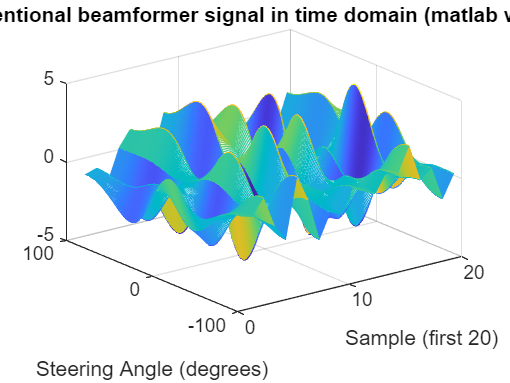

figure;
plotsamps = min(Nsamp, 20);
[x, y] = meshgrid(1:plotsamps, theta_scan);
mesh(x, y, real(sig_cbf(1:length(theta_scan), 1:plotsamps)));
ylabel('Steering Angle (degrees)');
xlabel('Sample (first 20)');
title('Conventional beamformer signal in time domain (matlab weights)');

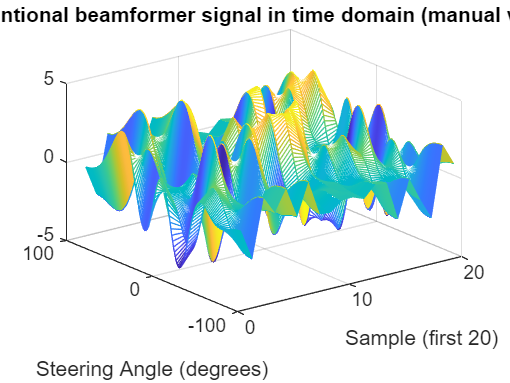

mesh(x, y, real(sig_cbf_manual(1:length(theta_scan), 1:plotsamps)));
ylabel('Steering Angle (degrees)');
xlabel('Sample (first 20)');
title('Conventional beamformer signal in time domain (manual weights)');

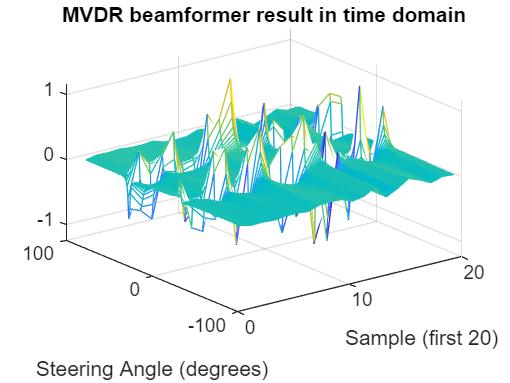

mesh(x, y, real(sig_mvdr(1:length(theta_scan), 1:plotsamps)));
ylabel('Steering Angle (degrees)');
xlabel('Sample (first 20)');
title('MVDR beamformer result in time domain');
grid on;

Normalize spectrum

P_mvdr = P_mvdr/max(P_mvdr);
P_mvdr2 = P_mvdr2/max(P_mvdr2);
P_cbf = P_cbf/max(P_cbf);
P_cbf_manual = P_cbf_manual/max(P_cbf_manual);

Plot results

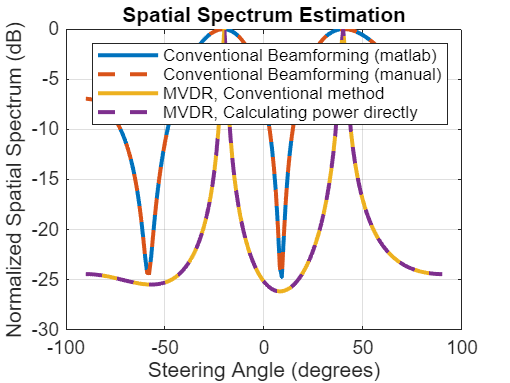

figure;
plot(theta_scan, 10*log10(P_cbf), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_cbf_manual), '--', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_mvdr), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_mvdr2), '--', 'LineWidth', 2);  % Convert power to dB
hold off;
legend('Conventional Beamforming (matlab)', 'Conventional Beamforming (manual)', 'MVDR, Conventional method', 'MVDR, Calculating power directly');  % Add a legend
xlabel('Steering Angle (degrees)');
ylabel('Normalized Spatial Spectrum (dB)');
title('Spatial Spectrum Estimation');
grid on;

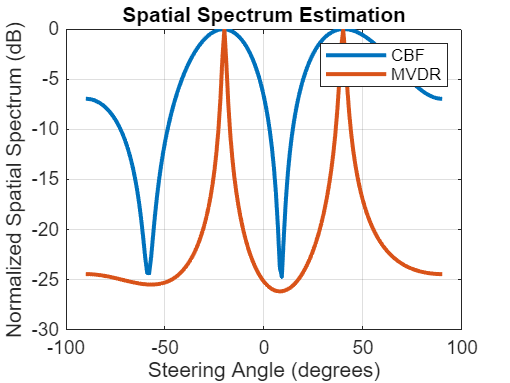

figure;
plot(theta_scan, 10*log10(P_cbf), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_mvdr), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
legend('CBF', 'MVDR');  % Add a legend
xlabel('Steering Angle (degrees)');
ylabel('Normalized Spatial Spectrum (dB)');
title('Spatial Spectrum Estimation');
grid on;